# Codigo para realizar ensayos sobre el modelo de la Grúa RTG 

`David Rodríguez Bascuñana`

## Datos de entrada

*Masa del contenedor*

Mc = 14100;

*Tiempo de simulación y periodo de muestreo*

Tend = 250;
Ts = 0.01;

*Referencias*

% Dimensiones contenedor
Xcont = 2.4384; % Metros
Ycont = 6.0960; % Metros
Zcont = 2.62128; % Metros
Zeq = 20.13;

% Tamaño bloque
TamX = 7;
TamY = 6;
TamZ = 5;

% Espacio entre contenedores
EspacioX = 0.5;
EspacioY = 0.5;
EspacioZ = 0;

L_vec = [4 10.5 16];
Mc_vec = [0.1 4700 14100 23520];

Posiciones iniciales

PosXini = 1;
PosYini = 1;
PosZini = 1;

Altura de elevación

PosZsub = 6; % si es mayor que 6 es altura máxima (1 metro de cable)

Posiciones Finales

PosXfin = 6;
PosYfin = 4;
PosZfin = 1; 

% Posiciones iniciales
Xini = (PosXini-1)*(Xcont+EspacioX);
Yini = -(PosYini-1)*(Ycont+EspacioY);
Zini = PosZini*Zcont;
Lini = Zeq-Zini;

%Altura intermedia
Zsub = PosZsub*Zcont;
Lsub = Zeq-Zsub;

if PosZsub>6
    Lsub = 1;
end

%posiciones finales
Xfin = (PosXfin-1)*(Xcont+EspacioX);
Yfin = -(PosYfin-1)*(Ycont+EspacioY);
Zfin = PosZfin*Zcont;
Lfin = Zeq-Zfin;

Tiempos de cambio

Ida

TstepCarroIda = 50;
TstepPorticoIda = 50;
TSubidaLIda = 0;
TBajadaLIda = 100;


Vuelta

TstepCarroVuelta = 170;
TstepPorticoVuelta = 170;
TSubidaLVuelta = 145;
TBajadaLVuelta = 220;


Tiempo desenganche

Tdesenganche = 140;
Mc_sim = [0 Mc; Tdesenganche Mc; Tdesenganche 0; Tend 0];
%Cálculo para la velocidad de elevación
Vmax = 52; % (m/min) sin carga
Vmin = 26; % (m/min) carga completa
CargaMax = 40641.9; % (Kg) = 40 Long Tons
VeleCarga = Vmax+((Vmin-Vmax)/CargaMax)*Mc; % (m/min)
VeleCarga = VeleCarga/60; % (m/s);
VeleVacio = Vmax/60; %sin carga

Tiempo transitorio

Ttrans = 10;
% Vectores para simulink

%Vector referencia carro
%RefXvec = [0 Xini;TstepCarroIda Xini;TstepCarroIda Xfin;TstepCarroVuelta Xfin;TstepCarroVuelta Xini; Tend Xini];
RefXvec = [0 Xini;TstepCarroIda-Ttrans Xini;TstepCarroIda Xfin;TstepCarroVuelta-Ttrans Xfin;TstepCarroVuelta Xini; Tend Xini];

%Vector referencia pórtico
RefYvec = [0 Yini;TstepPorticoIda-Ttrans Yini;TstepPorticoIda Yfin;TstepPorticoVuelta-Ttrans Yfin;TstepPorticoVuelta Yini;Tend Yini];

% Vector Longitud cable
Televado1 = TSubidaLIda+(Lsub-Lini)/-VeleCarga;
Tbajado1 = TBajadaLIda+(Lfin-Lsub)/VeleCarga;

Televado2 = TSubidaLVuelta+(Lfin-Lsub)/VeleVacio;
Tbajado2 = TBajadaLVuelta+(Lsub-Lini)/-VeleVacio;

LvecIda = [0 Lini;TSubidaLIda Lini;Televado1 Lsub;TBajadaLIda Lsub;Tbajado1 Lfin];
LvecVuelta = [TSubidaLVuelta Lfin;Televado2 Lsub;TBajadaLVuelta Lsub;Tbajado2 Lini;Tend Lini];
Lvec = [LvecIda;LvecVuelta];

## Simulación

%vt = 0:Ts:Tend; % Vector de tiempo
%load MATRICES_DE_GANANCIAS%MATPG.mat
load MATPG.mat
disp('Simulando ......, espere a que se presenten los resultados ')

Simulando ......, espere a que se presenten los resultados 


tic;
[vt,estados,registros] = sim('Simulacion_RTG_Planificacion_Ganancias_Anti_swing.slx');

%[vt,estados,registros] = sim('Simulacion_RTG_Planificacion_Ganancias_Anti_swing.slx');
Tsim = toc;
InformeSim = ['Simulación terminada con una duración de ', num2str(Tsim),' segundos'];
disp(InformeSim)

Simulación terminada con una duración de 4.3666 segundos


## Datos de salida

*Referencias y salidas*

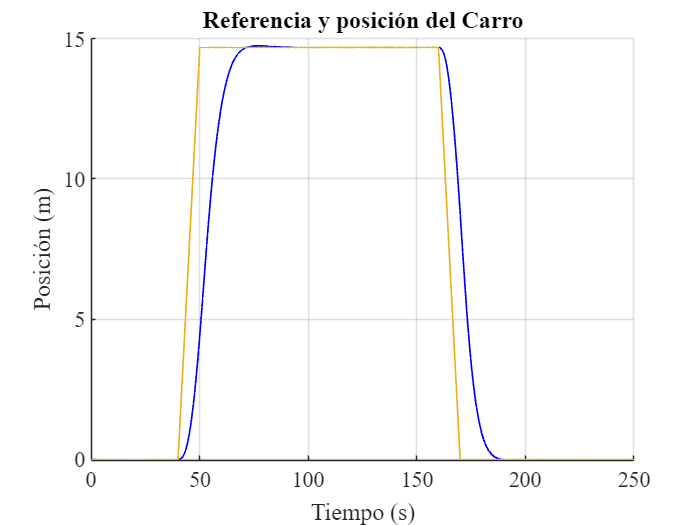

y = registros(:,1:3);
ref = registros(:,4:5);
u = registros(:,6:7);
pot = registros(:,8:9);

% Gráficas de las referencias y las salidas

figure, hold on
title('Referencia y posición del Carro','FontSize',15)
xlabel('Tiempo (s)')
ylabel('Posición (m)')
plot(vt,y(:,1),'LineWidth',1,'Color','b'), grid on
plot(vt,ref(:,1),'LineWidth',1,'Color','#EDB120')
set(gca,'fontname','times','FontSize',13)
hold off

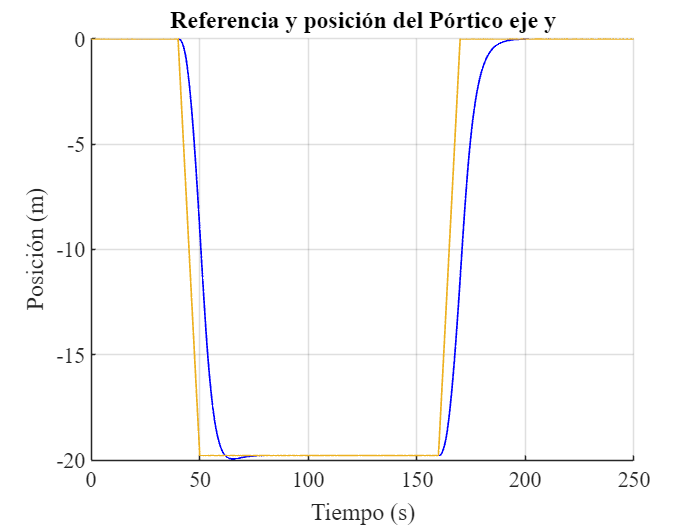

figure, hold on
title('Referencia y posición del Pórtico eje y','FontSize',15)
xlabel('Tiempo (s)')
ylabel('Posición (m)')
plot(vt,y(:,2),'LineWidth',1,'Color','b'), grid on
plot(vt,ref(:,2),'LineWidth',1,'Color','#EDB120')
set(gca,'fontname','times','FontSize',13)
hold off

*Acciones de control*

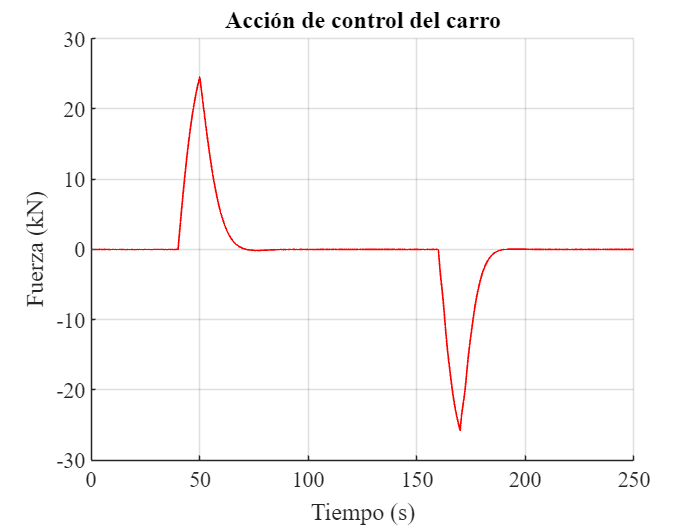

% Gráficas de las acciones de control

figure, hold on
title('Acción de control del carro','FontSize',15)
xlabel('Tiempo (s)')
ylabel('Fuerza (kN)')
plot(vt,u(:,2)/1000,'LineWidth',1,'Color','r'), grid on
set(gca,'fontname','times','FontSize',13)

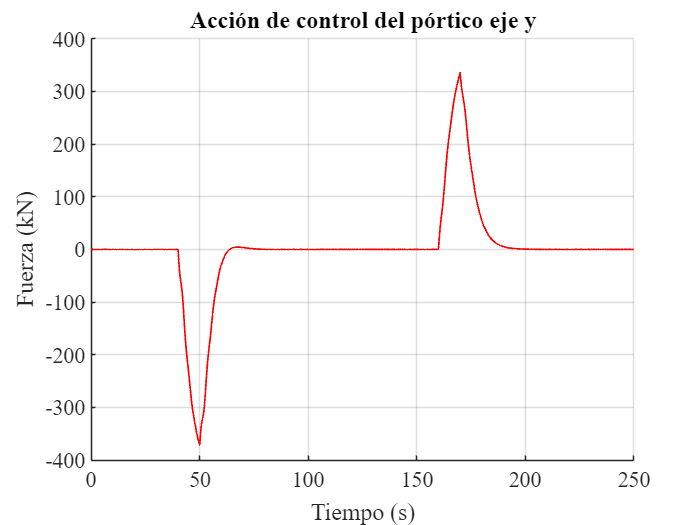

figure,  hold on
title('Acción de control del pórtico eje y','FontSize',15)
xlabel('Tiempo (s)')
ylabel('Fuerza (kN)')
plot(vt,u(:,1)/1000,'LineWidth',1,'Color','r'), grid on
set(gca,'fontname','times','FontSize',13)

*Potencias    *

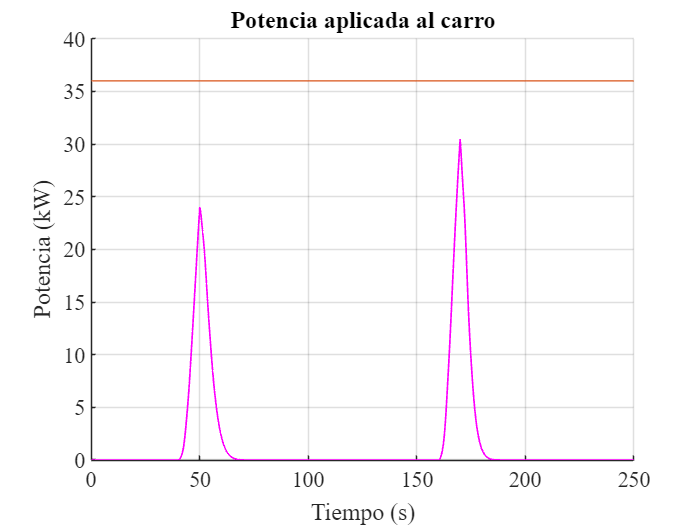

% Gráficas de la Potencia
Pot_C_Max = 36;
figure, hold on
title('Potencia aplicada al carro','FontSize',15)
xlabel('Tiempo (s)')
ylabel('Potencia (kW)')
plot(vt,pot(:,1)/1000,'LineWidth',1,'Color','m'), grid on, plot(vt,Pot_C_Max*ones(size(vt)))
set(gca,'fontname','times','FontSize',13)

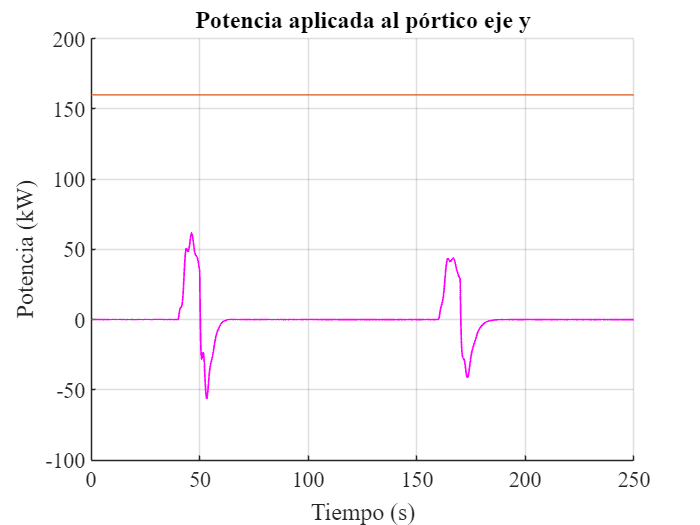

Pot_P_Max = 160;
figure, hold on
title('Potencia aplicada al pórtico eje y','FontSize',15)
xlabel('Tiempo (s)')
ylabel('Potencia (kW)')
plot(vt,pot(:,2)/1000,'LineWidth',1,'Color','m'), grid on, plot(vt,Pot_P_Max*ones(size(vt)))
set(gca,'fontname','times','FontSize',13)

Trayectoria 2D x-y

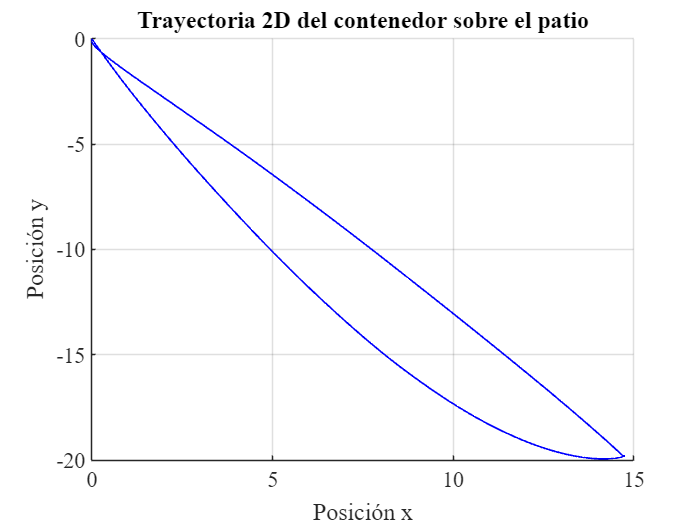

figure, hold on
title('Trayectoria 2D del contenedor sobre el patio','FontSize',15)
xlabel('Posición x')
ylabel('Posición y')
plot(y(:,1),y(:,2),'LineWidth',1,'Color','b'), grid on
set(gca,'fontname','times','FontSize',13)
hold off

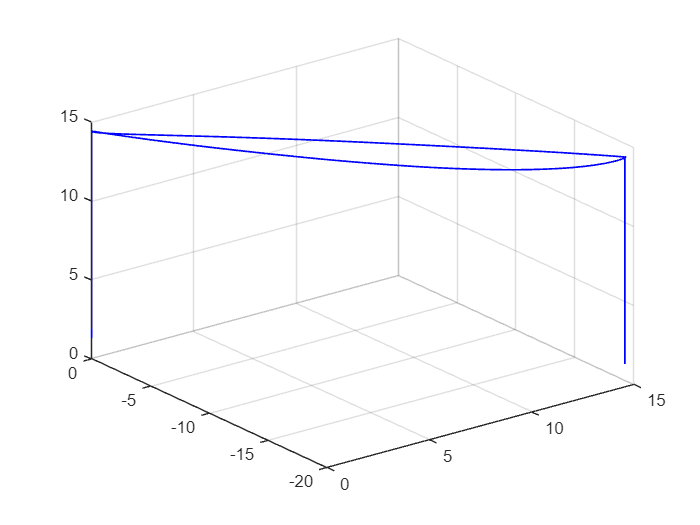

%title('Trayectoria 3D del contenedor sobre el patio','FontSize',15)
%xlabel('Posición x')
%ylabel('Posición y')
plot3(y(:,1),y(:,2),y(:,3),'LineWidth',1,'Color','b'), grid on

## Estadísticas y cálculos

### Acciones de control

*Fuerza máxima aplicada (kN)*

FmaxC = max(u(:,1))/1000 % kN

FmaxC = 335.1973

FmaxPy = max(u(:,2))/1000 % kN

FmaxPy = 24.5304

*Potencia máxima aplicada (kW) y % de potencia total*

PotTotalC = 9*4; % kW
PotTotalPy = 8*20; % kW
PotMaxC = max(pot(:,1))/1000 % kW

PotMaxC = 30.4426

PotMaxPy = max(pot(:,2))/1000 % kW

PotMaxPy = 61.5064

PorcentajePotC = (PotMaxC/PotTotalC)*100

PorcentajePotC = 84.5627

PorcentajePotPy = (PotMaxPy/PotTotalPy)*100

PorcentajePotPy = 38.4415